# A Simulation of Alvino Mario Fantini's Prioritizations Between Spanish and English

clear all;
% Defining initial vocabulary:
p_10 = 0.8;
p_20 = 0.2;
s = .05; % Learning rate
n = 2; % number of variants
T = 2000; % Number of time steps to take
% Probabilities of hearing either form:
probForm1 = 0.49

probForm1 = 0.4900

probForm2 = 0.51

probForm2 = 0.5100

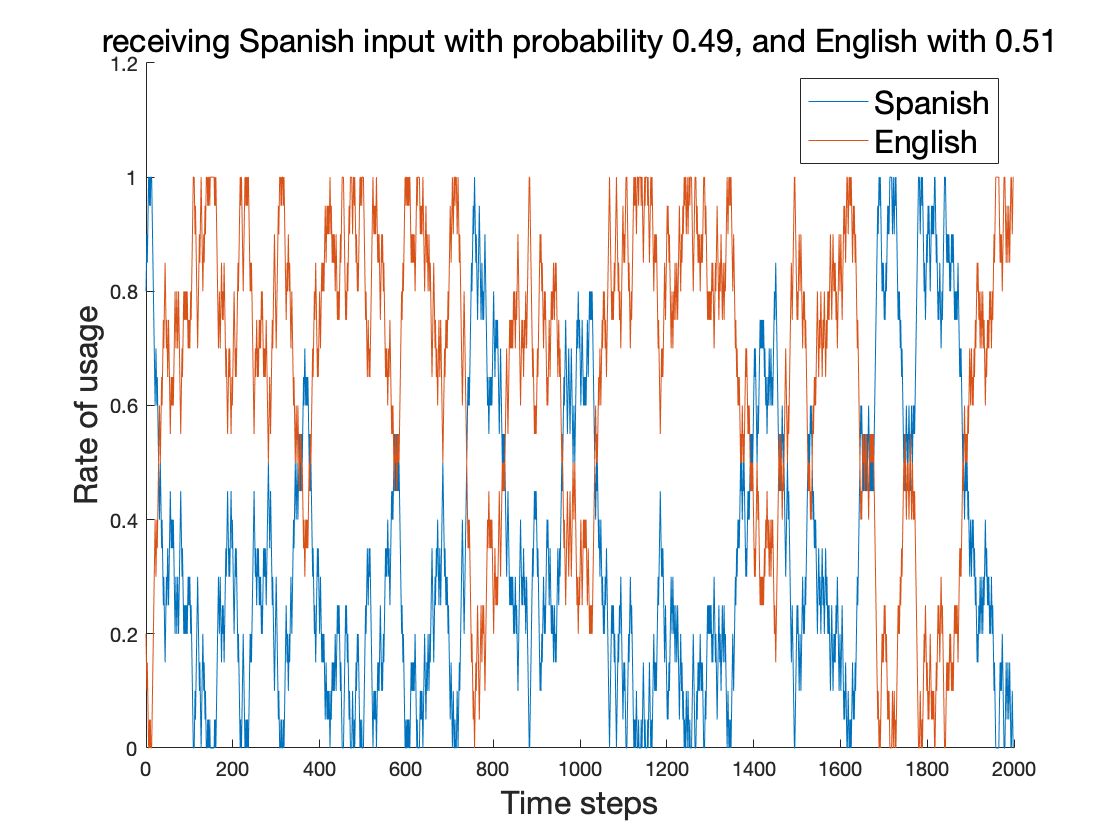



% Define our initial vectors with x1 and x2 values as empty 
P1 = NaN(T, 1);
P2 = NaN(T, 1);
P1(1) = p_10;
P2(1) = p_20;
% First plot the growth of form x_0
for t = 2:T
    u = rand;
    if u < probForm1
        P1(t) = P1(t-1) + F(P2(t-1),n,s);
        P2(t) = P2(t-1) - F(P2(t-1),n,s);
    else 
        P1(t) = P1(t-1) - F(P1(t-1),n,s);
        P2(t) = P2(t-1) + F(P1(t-1),n,s);
    end
end
figure
TVector = 0:1:(T-1);
hold on;
plot(TVector, P1);
plot(TVector, P2);
legend("Spanish", "English", 'FontSize', 16)
%title("Mario's simulated usage rates of Spanish and English", 'FontSize',18)
subtitle("receiving Spanish input with probability 0.49, and English with 0.51", 'FontSize',16)
xlabel("Time steps", 'FontSize',16)
ylabel("Rate of usage", 'FontSize',16)

function [out] = F(x, n, s)
    comparator = s / (n-1);
    if x < comparator
        out = x;
    else
        out = comparator;
    end
end
